##  Задание 3. (Необязательное) Регулятор с качественной экспоненциальной устойчивостью.

Начальные условия на задание:

A = [12, -1, 14; 
     6, 0, 6;
     -6, -2, -8]

A =     12    -1    14
     6     0     6
    -6    -2    -8


B = [11;
      7;
      -7]

B =     11
     7
    -7


Сделать вывод об управляемости и стабилизируемости системы...

U = ctrb(A, B)

U =     11    27   -36
     7    24    18
    -7   -24   -18


U = [B , A*B , A^2 * B]

U =     11    27   -36
     7    24    18
    -7   -24   -18


rank(U)

ans = 2

Проверка критерия Хаутуса:

EIG_A = eig(A)

EIG_A =    3.0000 + 3.0000i
   3.0000 - 3.0000i
  -2.0000 + 0.0000i


l1 = 3 + 3j; l2 = 3 - 3j; l3 = -2;

vpa([A - eye(3).*l1 , B])

$$ans = \left(\begin{array}{cccc} 9.0-3.0\,\mathrm{i} & -1.0 & 14.0 & 11.0\\ 6.0 & -3.0-3.0\,\mathrm{i} & 6.0 & 7.0\\ -6.0 & -2.0 & -11.0-3.0\,\mathrm{i} & -7.0 \end{array}\right)$$

vpa([A - eye(3).*l2 , B])

$$ans = \left(\begin{array}{cccc} 9.0+3.0\,\mathrm{i} & -1.0 & 14.0 & 11.0\\ 6.0 & -3.0+3.0\,\mathrm{i} & 6.0 & 7.0\\ -6.0 & -2.0 & -11.0+3.0\,\mathrm{i} & -7.0 \end{array}\right)$$

vpa([A - eye(3).*l3 , B])

$$ans = \left(\begin{array}{cccc} 14.0 & -1.0 & 14.0 & 11.0\\ 6.0 & 2.0 & 6.0 & 7.0\\ -6.0 & -2.0 & -6.0 & -7.0 \end{array}\right)$$


rank([A - eye(3).*l1 , B])

ans = 3

rank([A - eye(3).*l2 , B])

ans = 3

rank([A - eye(3).*l3 , B])

ans = 2

**A --> Стабилизируема, но не управляема**

Тогда придётся применять метод усечения, чтобы численные методы лучше вычислялись, да и с управляемой системой лучше работается

[P,Aj] = jordan(A)

P =   -1.0000 + 0.0000i  -1.5000 + 0.5000i  -1.5000 - 0.5000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


Aj =   -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   3.0000 - 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.0000 + 3.0000i


[P2, Aj2] = cdf2rdf(P,Aj)

P2 =    -1.0000   -2.1213    0.7071
         0   -1.4142         0
    1.0000    1.4142         0


Aj2 =     -2     0     0
     0     3    -3
     0     3     3



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 
 
Aj1= P1^-1 * A * P1

Aj1 =     -2     0     0
     0     3     3
     0    -3     3


Bj = P1^-1 * B

Bj =      0
     1
    -7



A_reduced = inv(P1) * A * P1 ; A_reduced(1,:)=[]; A_reduced(:,1)=[]

A_reduced =      3     3
    -3     3


B_reduced = inv(P1) * B ; B_reduced(1,:) = []

B_reduced =      1
    -7


Другая подготовка, симуляции

C = [1 1 1];
x0 = [1 1 1]';
simTimeStart = 0;
simTimeEnd = 5;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);

Введём параметры регулятора в соответствии с одним неуправляемым собственным числом (это число будет внутри нашего комплексно-значного круга)

beta = -5/2; k = 2; r = abs(beta)/k;

A = [5 8 5; -6 -9 -8; 6 6 5];
B = [2; 0; 0];
x0 = [1;1;1];

[P,Aj]=jordan(A);
P1(:,1)=real(P(:,1));
P1(:,2)=imag(P(:,2));
P1(:,3)=real(P(:,3));
Aj=P1^-1*A*P1;
Bj=P1^-1*B;

Aj1 = Aj;
Aj1(1,:) = [];
Aj1(:,1) = [];
Bj1 = Bj;
Bj1(1, :) = [];

A_reduced = Aj1;
B_reduced = Bj1;

beta = -4.5;
r = 3;

Q = zeros([2 2]); R = 1; 
syms P_ [2 2];
beta_i = beta*eye(2);

KK = -(R +B_reduced'*P_*B_reduced)^-1 * B_reduced'*P_*(A_reduced-beta_i);
equation = [(A_reduced + B_reduced*KK - beta_i)'*P_*(A_reduced + B_reduced*KK - beta_i) - r^2 * P_  == -Q];
s = vpasolve(equation,[P_], Random=true);
P_=[s.P_1_1 s.P_1_2; s.P_2_1 s.P_2_2];
K = [ 0 -(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))]*inv(P1);
K = double(round(K, 5))

K =      0     0     0


% Wait Casino for providing us a numbers with negative real part..
EIG_K3 =  eig(A + B * K)

EIG_K3 =    2.0000 + 3.0000i
   2.0000 - 3.0000i
  -3.0000 + 0.0000i


Зададимся четырьмя наборами параметров Q,R:

## 1 -- Q = I ; R = 1;

Q = eye(2); R = 1; 
syms P_ [2 2];
beta_i = beta*eye(2);

equation = [(A_reduced-B_reduced*(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))- ...
beta_i)'*P_*(A_reduced-B_reduced*(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))- ...
beta_i)-r*2*P_ == -Q];

s = vpasolve(equation,[P_], Random=true)

s = struct with fields:
    P_1_1: -0.22036940498779376560636667573976
    P_2_1: 0.085240669444785221066401165088993
    P_1_2: 0.085240669444785221066401165088993
    P_2_2: -0.065790569379097438904209041922415


P_=[s.P_1_1 s.P_1_2; s.P_2_1 s.P_2_2]

$$P\_ = \left(\begin{array}{cc} -0.22036940498779376560636667573976 & 0.085240669444785221066401165088993\\ 0.085240669444785221066401165088993 & -0.065790569379097438904209041922415 \end{array}\right)$$

K = [ 0 -(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))]*inv(P1);
K = double(round(K, 5))

K =    -5.3466   -5.3466   -2.5038


% Wait Casino for providing us a numbers with negative real part..
EIG_K1 =  eig(A + B * K)

EIG_K1 =    -7.9963
    1.3032
   -3.0000


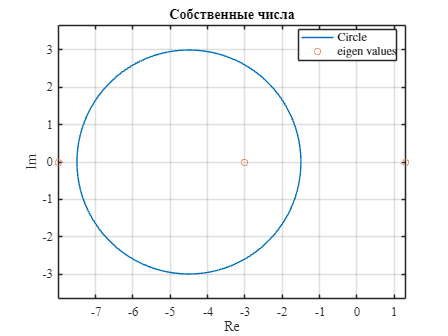


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
th = 0:pi/50:2*pi;
xunit = r * cos(th) + beta;
yunit = r * sin (th);
plot(xunit, yunit); hold on;
plot(real(EIG_K1), imag(EIG_K1), "o"); 
grid on; axis equal;
xlabel('Re'); ylabel('Im');                                   
legend('Circle', 'eigen values', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Собственные числа')
save_file("plot_circle1");

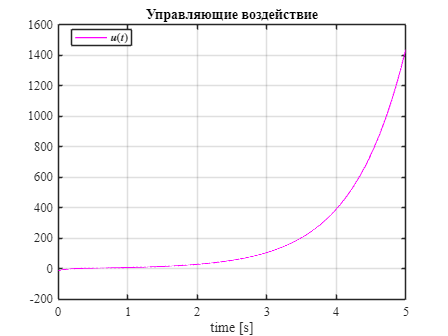

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u1 = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u1, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("ctrl_exp_u1");

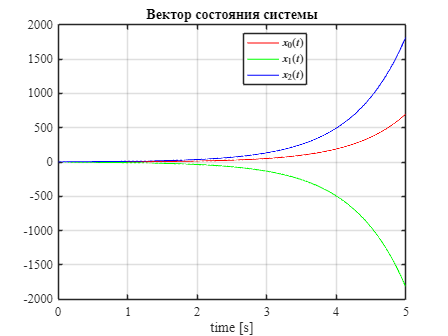


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl_exp_x1");

## 2 -- Q = I ; R = 0;

Q = eye(2); R = 0; 
syms P_ [2 2];
beta_i = beta*eye(2);

equation = [(A_reduced-B_reduced*(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))- ...
beta_i)'*P_*(A_reduced-B_reduced*(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))- ...
beta_i)-r*2*P_ == -Q];

s = vpasolve(equation,[P_], Random=true)

s = struct with fields:
    P_1_1: 0.13434845253890285931724212448545
    P_2_1: 0.070022797276821582590419841392643
    P_1_2: 0.070022797276821582590419841392643
    P_2_2: 0.014950605900219904387423676982608


P_=[s.P_1_1 s.P_1_2; s.P_2_1 s.P_2_2]

$$P\_ = \left(\begin{array}{cc} 0.13434845253890285931724212448545 & 0.070022797276821582590419841392643\\ 0.070022797276821582590419841392643 & 0.014950605900219904387423676982608 \end{array}\right)$$

K = [ 0 -(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))]*inv(P1);
K = double(round(K, 5))

K =    -2.4682   -2.4682    0.3629


% Wait Casino for providing us a numbers with negative real part..
EIG_K2 =  eig(A + B * K)

EIG_K2 =     3.5636
   -4.5000
   -3.0000


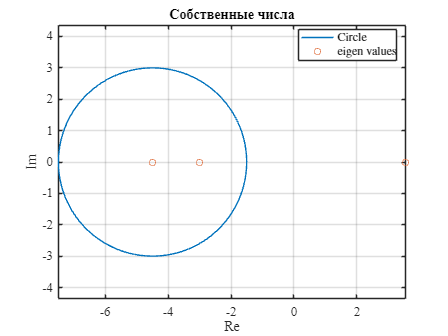


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
th = 0:pi/50:2*pi;
xunit = r * cos(th) + beta;
yunit = r * sin (th);
plot(xunit, yunit); hold on;
plot(real(EIG_K2), imag(EIG_K2), "o"); 
grid on; axis equal;
xlabel('Re'); ylabel('Im');                                   
legend('Circle', 'eigen values', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Собственные числа')
save_file("plot_circle2");

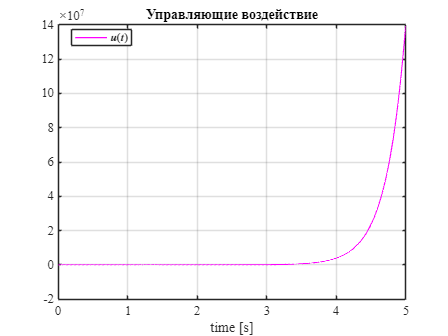

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u2 = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u2, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("ctrl_exp_u2");

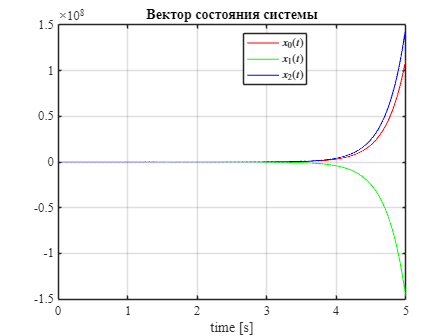


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl_exp_x2");

## 3 -- Q = 0 ; R = 1;

Q = zeros([2 2]); R = 1; 
syms P_ [2 2];
beta_i = beta*eye(2);



KK = -(R +B_reduced'*P_*B_reduced)^-1 * B_reduced'*P_*(A_reduced-beta_i);
equation = [(A_reduced + B_reduced*KK - beta_i)'*P_*(A_reduced + B_reduced*KK - beta_i) - r^2 * P_  == -Q];
s = vpasolve(equation,[P_], Random=true);
P_=[s.P_1_1 s.P_1_2; s.P_2_1 s.P_2_2];
K = [ 0 -(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))]*inv(P1);
K = double(round(K, 5))

K =    -1.5030   -1.5030    1.1411


% Wait Casino for providing us a numbers with negative real part..
EIG_K3 =  eig(A + B * K)

EIG_K3 =     4.4933
   -3.4993
   -3.0000


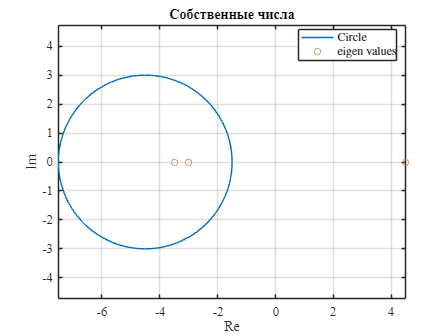



% equation = [(A_reduced-B_reduced*(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))- ...
% beta_i)'*P_*(A_reduced-B_reduced*(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))- ...
% beta_i)-r*2*P_ == -Q];
% 
% s = vpasolve(equation,[P_], Random=true)
% P_=[s.P_1_1 s.P_1_2; s.P_2_1 s.P_2_2]
% K = [ 0 -(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))]*inv(P1);
% K = double(round(K, 5))
% % Wait Casino for providing us a numbers with negative real part..
% EIG_K =  eig(A + B * K)

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
th = 0:pi/50:2*pi;
xunit = r * cos(th) + beta;
yunit = r * sin (th);
plot(xunit, yunit); hold on;
plot(real(EIG_K3), imag(EIG_K3), "o"); 
grid on; axis equal;
xlabel('Re'); ylabel('Im');                                   
legend('Circle', 'eigen values', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Собственные числа')
save_file("plot_circle3");

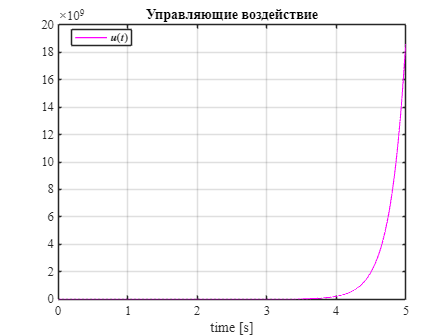

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u3 = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u3, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("ctrl_exp_u3");

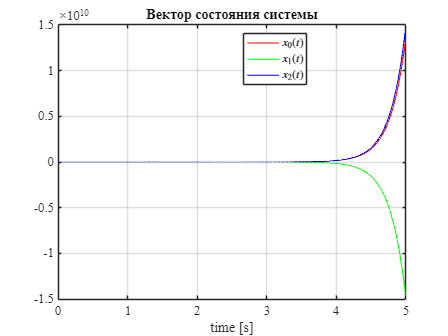


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl_exp_x3");

## 4 -- Q = 0 ; R = 0;

Q = zeros([2 2]); R = 0; 
syms P_ [2 2];
beta_i = beta*eye(2);

KK = -(R +B_reduced'*P_*B_reduced)^-1 * B_reduced'*P_*(A_reduced-beta_i);
equation = [(A_reduced + B_reduced*KK - beta_i)'*P_*(A_reduced + B_reduced*KK - beta_i) - r^2 * P_  == -Q]

$$equation = \begin{array}{l} \left(\begin{array}{cc} 9\,P_{2,2}-9\,P_{1,1}-\frac{9\,P_{1,2}\,\bar{P_{1,2}}}{\bar{P_{1,1}}}-\frac{3\,P_{1,2}\,\sigma_{2}}{P_{1,1}}=0 & \sigma_{3}-\frac{39\,P_{2,2}}{2}-9\,P_{1,2}+\frac{13\,P_{1,2}\,\sigma_{2}}{2\,P_{1,1}}=0\\ \sigma_{3}-\frac{39\,P_{2,2}}{2}-9\,P_{2,1}+\frac{3\,P_{1,2}\,\sigma_{1}}{P_{1,1}}=0 & \frac{133\,P_{2,2}}{4}-\frac{169\,P_{1,2}\,\bar{P_{1,2}}}{4\,\bar{P_{1,1}}}-\frac{13\,P_{1,2}\,\sigma_{1}}{2\,P_{1,1}}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{13\,P_{2,1}}{2}-\frac{13\,P_{1,1}\,\bar{P_{1,2}}}{2\,\bar{P_{1,1}}}\\ \sigma_{2}=3\,P_{2,1}-\frac{3\,P_{1,1}\,\bar{P_{1,2}}}{\bar{P_{1,1}}}\\ \sigma_{3}=\frac{39\,P_{1,2}\,\bar{P_{1,2}}}{2\,\bar{P_{1,1}}} \end{array}$$

s = vpasolve(equation,[P_], Random=true)

s = struct with fields:
    P_1_1: 2.3418051520287758947814673202474e-39
    P_2_1: -6.2448137387434023860839128539932e-39
    P_1_2: -8.9539608754041431271056103421226e-39
    P_2_2: 2.1156602427397225363148256231451e-38


P_=[s.P_1_1 s.P_1_2; s.P_2_1 s.P_2_2]

$$P\_ = \left(\begin{array}{cc} 2.3418051520287758947814673202474e-39 & -8.9539608754041431271056103421226e-39\\ -6.2448137387434023860839128539932e-39 & 2.1156602427397225363148256231451e-38 \end{array}\right)$$

K = [ 0 -(inv(R+B_reduced'*P_*B_reduced)*B_reduced'*P_*(A_reduced-beta_i))]*inv(P1);
K = double(round(K, 5))

K =    -8.9853   -8.9853   -9.9559


% Wait Casino for providing us a numbers with negative real part..
EIG_K4 =  eig(A + B * K)

EIG_K4 =    -9.4706
   -4.5000
   -3.0000


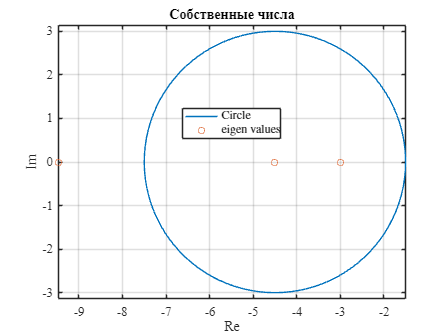


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
th = 0:pi/50:2*pi;
xunit = r * cos(th) + beta;
yunit = r * sin (th);
plot(xunit, yunit); hold on;
plot(real(EIG_K4), imag(EIG_K4), "o"); 
grid on; axis equal;
xlabel('Re'); ylabel('Im');                                   
legend('Circle', 'eigen values', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Собственные числа')
save_file("plot_circle4");

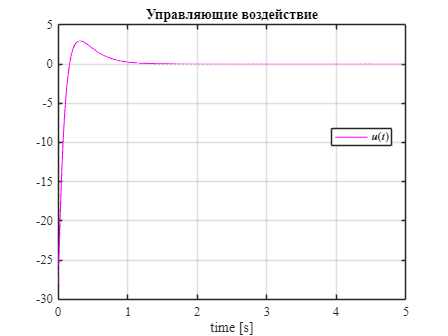

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u4 = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u4, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("ctrl_exp_u4");

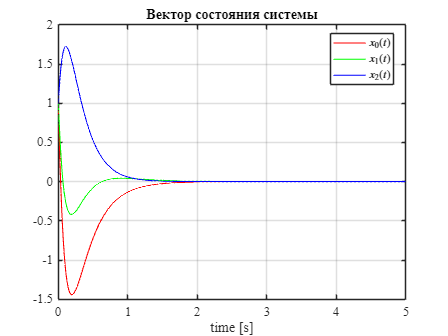


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl_exp_x4");

## Общие графики

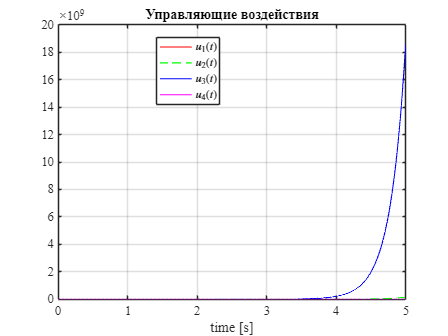

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u1, 'r', 'LineWidth', 1.0); hold on; grid on;
plot(time, u2, 'g--', 'LineWidth', 1.0); 
plot(time, u3, 'b', 'LineWidth', 1.0); 
plot(time, u4, 'magenta', 'LineWidth', 1.0); 
xlabel('time [s]');                                   
legend('$u_1(t)$', '$u_2(t)$', '$u_3(t)$', '$u_4(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействия')
save_file("ctrl_exp_u_all");

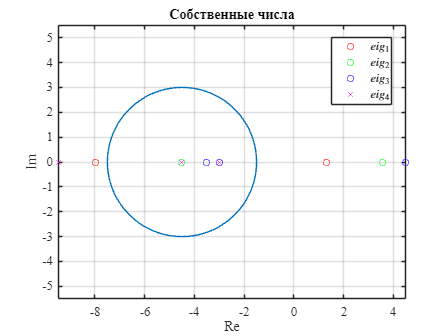


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
th = 0:pi/50:2*pi;
xunit = r * cos(th) + beta;
yunit = r * sin (th);
plot(xunit, yunit); hold on;
plot(real(EIG_K1), imag(EIG_K1), "ro"); 
plot(real(EIG_K2), imag(EIG_K2), "go"); 
plot(real(EIG_K3), imag(EIG_K3), "bo"); 
plot(real(EIG_K4), imag(EIG_K4),'x', 'Color', 'magenta'); 
grid on; axis equal;
xlabel('Re'); ylabel('Im');                                   
legend('', '$eig_1$', '$eig_2$', '$eig_3$', '$eig_4$',  ...
        'Location', 'best', 'Interpreter', 'latex');
title('Собственные числа')
save_file("plot_circle_all");

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab9\latex9\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end